rgbtomato = imread('OIP.jpg');
labtomato = rgb2lab(rgbtomato);
tomatoab = labtomato(:,:,2);
tomatoab = im2single(tomatoab);
ncolors = 3

ncolors = 3

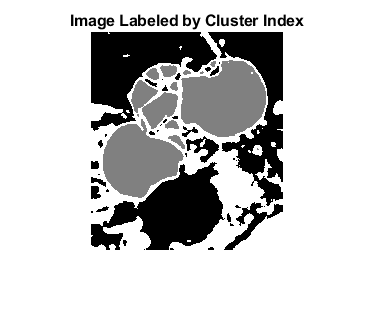

pixel_labels = imsegkmeans(tomatoab,ncolors,'NumAttempts',10);
imshow(pixel_labels,[])
title('Image Labeled by Cluster Index');

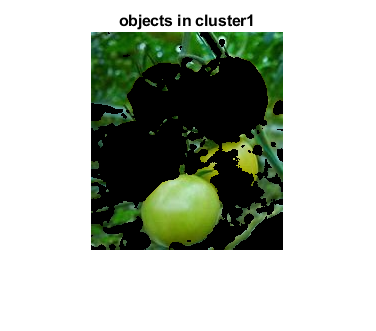

mask1 = pixel_labels == 1;
cluster1 = rgbtomato .*uint8(mask1);
imshow(cluster1)
title('objects in cluster1');

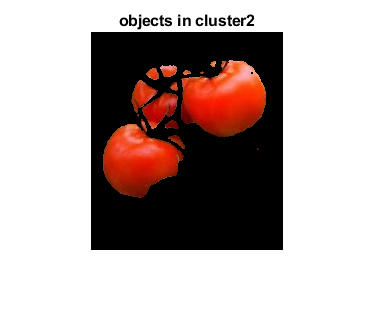

mask2= pixel_labels == 2;
cluster2= rgbtomato .*uint8(mask2);
imshow(cluster2)
title('objects in cluster2');

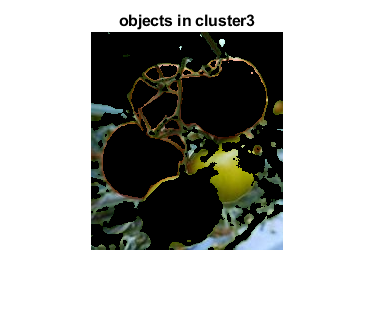

mask3 = pixel_labels == 3;
cluster3= rgbtomato .*uint8(mask3);
imshow(cluster3)
title('objects in cluster3');